# Machine Learning Online Class - Exercise 2: Logistic Regression

推荐实时脚本模式

## Initialization

clear ; close all; clc;

## Load Data

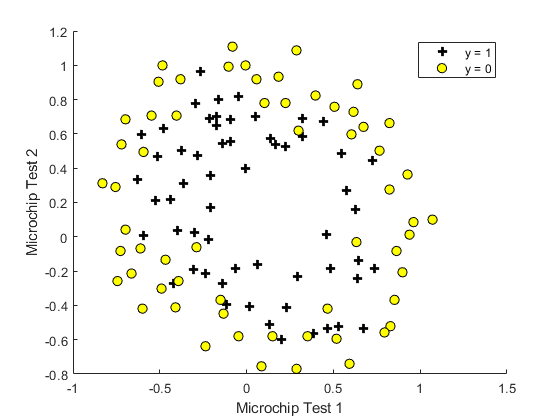

data = load('ex2data2.txt');
X = data(:, [1, 2]); y = data(:, 3);

plotData(X, y);

% Put some labels
hold on;

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

% Specified in plot order
legend('y = 1', 'y = 0')
hold off;

## =========== Part 1: Regularized Logistic Regression ============

% Add Polynomial Features

% Note that mapFeature also adds a column of ones for us, so the intercept
% term is handled
X = mapFeature(X(:,1), X(:,2));

X1^1 ; X2^0
X1^0 ; X2^1
X1^2 ; X2^0
X1^1 ; X2^1
X1^0 ; X2^2
X1^3 ; X2^0
X1^2 ; X2^1
X1^1 ; X2^2
X1^0 ; X2^3
X1^4 ; X2^0
X1^3 ; X2^1
X1^2 ; X2^2
X1^1 ; X2^3
X1^0 ; X2^4
X1^5 ; X2^0
X1^4 ; X2^1
X1^3 ; X2^2
X1^2 ; X2^3
X1^1 ; X2^4
X1^0 ; X2^5
X1^6 ; X2^0
X1^5 ; X2^1
X1^4 ; X2^2
X1^3 ; X2^3
X1^2 ; X2^4
X1^1 ; X2^5
X1^0 ; X2^6


此处输出结果出现问题，一般是因为上述的X加1列的操作执行了多次

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1
lambda = 1;

% Compute and display initial cost and gradient for regularized logistic
% regression
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);

fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


fprintf('Expected cost (approx): 0.693\n');

Expected cost (approx): 0.693


fprintf('Gradient at initial theta (zeros) - first five values only:\n');

Gradient at initial theta (zeros) - first five values only:


fprintf(' %f \n', grad(1:5));

 0.008475 
 0.018788 
 0.000078 
 0.050345 
 0.011501 


fprintf('Expected gradients (approx) - first five values only:\n');

Expected gradients (approx) - first five values only:


fprintf(' 0.0085\n 0.0188\n 0.0001\n 0.0503\n 0.0115\n');

 0.0085
 0.0188
 0.0001
 0.0503
 0.0115


% Compute and display cost and gradient
% with all-ones theta and lambda = 10
test_theta = ones(size(X, 2), 1);
[cost, grad] = costFunctionReg(test_theta, X, y, 10);

fprintf('\nCost at test theta (with lambda = 10): %f\n', cost);


Cost at test theta (with lambda = 10): 3.164509


fprintf('Expected cost (approx): 3.16\n');

Expected cost (approx): 3.16


fprintf('Gradient at test theta - first five values only:\n');

Gradient at test theta - first five values only:


fprintf(' %f \n', grad(1:5));

 0.346045 
 0.161352 
 0.194796 
 0.226863 
 0.092186 


fprintf('Expected gradients (approx) - first five values only:\n');

Expected gradients (approx) - first five values only:


fprintf(' 0.3460\n 0.1614\n 0.1948\n 0.2269\n 0.0922\n');

 0.3460
 0.1614
 0.1948
 0.2269
 0.0922



Program paused. Press enter to continue.


## ============= Part 2: Regularization and Accuracies =============

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1 (you should vary this)
lambda = 1;

% Set Options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



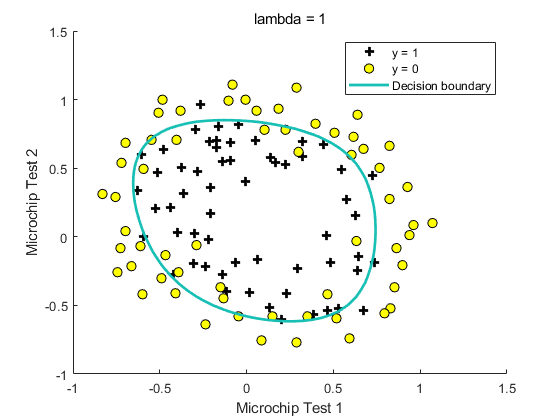

% Plot Boundary
plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;

% Compute accuracy on our training set
p = predict(theta, X);

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 83.050847


fprintf('Expected accuracy (with lambda = 1): 83.1 (approx)\n');

Expected accuracy (with lambda = 1): 83.1 (approx)
